Proyecto Final 

Abdías Aragon Rafols, Gonzalo Pacheco Agredano, Sergio Ramírez Rodas

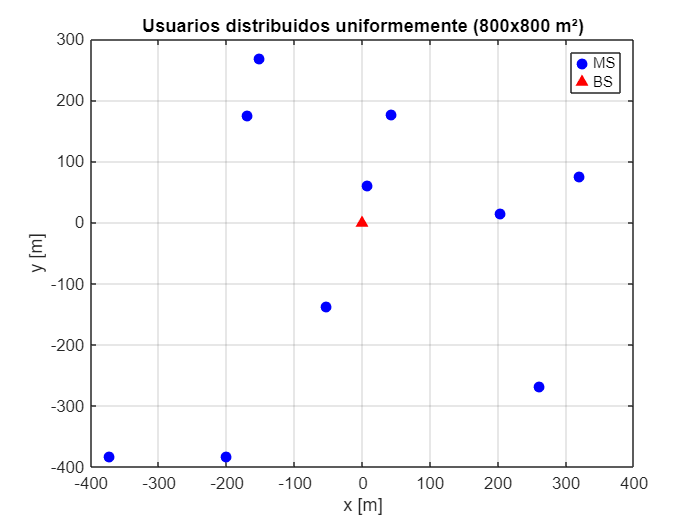

clear all; clc;


B = 10*10^6;            % B = 10 MHz
f = 1.8*10^9;           % f = 1.8 GHz
Ptx = 20;               % Ptx = 20 W
Num_Tramas = 1e6;
N0 = 10^-20;
sigma_sh = 1.5;
fd_values = [5 50 120];
ts = 1/B;

% Estación base en el origen
Pos_BS = 0 + 1i * 0;

% Número de usuarios
K = 10;

% -------------------------------
% Opción 1: Área rectangular 800x800 m
lado_x = 800;
lado_y = 800;
option1 = 1;
Pos_MS1 = Calc_Pos_MS(option1, K, 0, 0, lado_x, lado_y);

% -------------------------------
% Opción 2: Usuarios a 150 m de la estación base
lado_x2 = 150;
lado_y2 = 150;
option2 = 2;
Pos_MS2 = Calc_Pos_MS(option2, K, lado_x2, lado_y2, lado_x, lado_y);

% -------------------------------
% Visualización
figure;
plot(real(Pos_MS1), imag(Pos_MS1), 'bo', 'MarkerFaceColor', 'b');
hold on;
plot(real(Pos_BS), imag(Pos_BS), 'r^', 'MarkerFaceColor', 'r');
title('Usuarios distribuidos uniformemente (800x800 m²)');
xlabel('x [m]'); ylabel('y [m]');
grid on; legend('MS','BS');

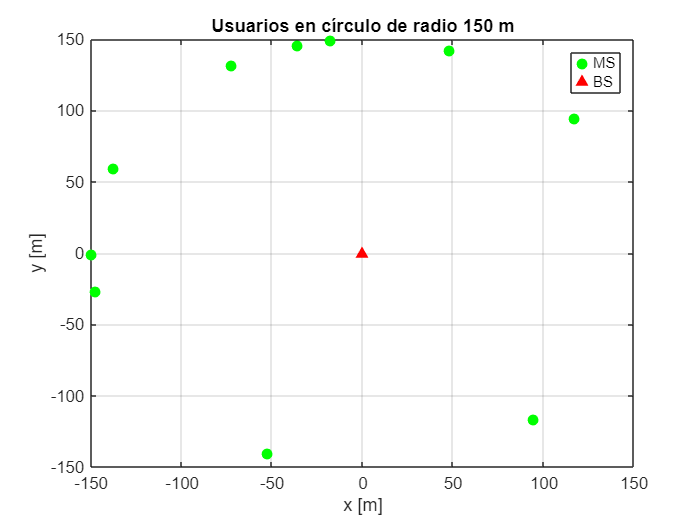


figure;
plot(real(Pos_MS2), imag(Pos_MS2), 'go', 'MarkerFaceColor', 'g');
hold on;
plot(real(Pos_BS), imag(Pos_BS), 'r^', 'MarkerFaceColor', 'r');
title('Usuarios en círculo de radio 150 m');
xlabel('x [m]'); ylabel('y [m]');
grid on; legend('MS','BS');

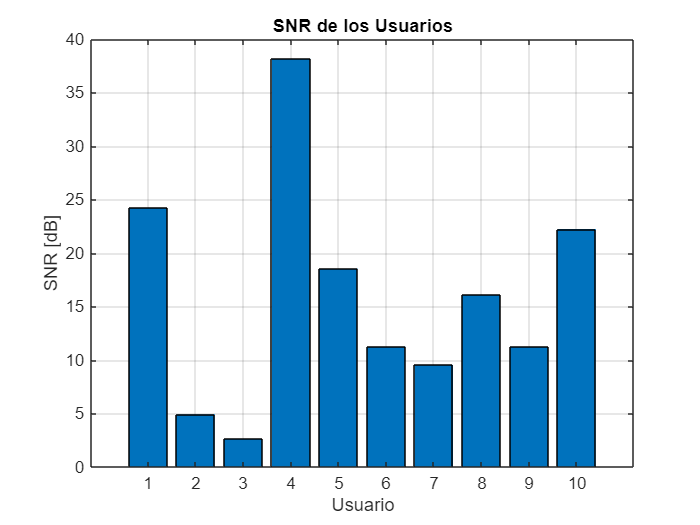

% Cálculo de la SNR para cada usuario (en un único instante)
SNRs = zeros(K, 1); % Matriz para almacenar las SNRs de cada usuario

for k = 1:K
    % Cálculo de la distancia entre la estación base y el usuario k
    dist = abs(Pos_BS - Pos_MS1(k)); % Distancia de la estación base al usuario
    % Cálculo de la SNR para el usuario k
    SNRs(k) = calcular_SNRs(Pos_BS, Pos_MS1(k), Ptx, B, f, sigma_sh, N0);
end

% -------------------------------
% Visualización de las SNRs de los usuarios
figure;
bar(SNRs); % Representación gráfica en barras
title('SNR de los Usuarios');
xlabel('Usuario');
ylabel('SNR [dB]');
grid on;


SNR_avg = mean(SNRs);        % SNR media aleatoria para cada usuario (en dB)
delay_vector = zeros(1, K);       % Inicialización del vector de retrasos (todos a 0)
algoritmo = 'utilidad';            % Elige el algoritmo ('maxSNR' o 'utilidad')
num_muestras = 9600;                  % Número de tramas a simular


SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(3), num_muestras,ts)

SNR_instantanea =    51.2007   51.2005   51.2003   51.2001   51.1999   51.1997   51.1996   51.1994   51.1992   51.1990   51.1988   51.1986   51.1984   51.1982   51.1980   51.1978   51.1976   51.1974   51.1972   51.1970   51.1968   51.1966   51.1964   51.1962   51.1960   51.1958   51.1956   51.1954   51.1952   51.1950   51.1948   51.1947   43.6747   43.6750   43.6753   43.6756   43.6760   43.6763   43.6766   43.6770   43.6773   43.6776   43.6779   43.6783   43.6786   43.6789   43.6792   43.6796   43.6799   43.6802
    2.0365    2.0359    2.0354    2.0348    2.0343    2.0337    2.0332    2.0326    2.0321    2.0315    2.0310    2.0305    2.0299    2.0294    2.0288    2.0283    2.0277    2.0272    2.0266    2.0261    2.0255    2.0250    2.0244    2.0239    2.0233    2.0228    2.0222    2.0217    2.0211    2.0206    2.0200    2.0195   12.6609   12.6606   12.6604   12.6601   12.6598   12.6596   12.6593   12.6591   12.6588   12.6586   12.6583   12.6580   12.6578   12.6575   12.6573   12.6570 

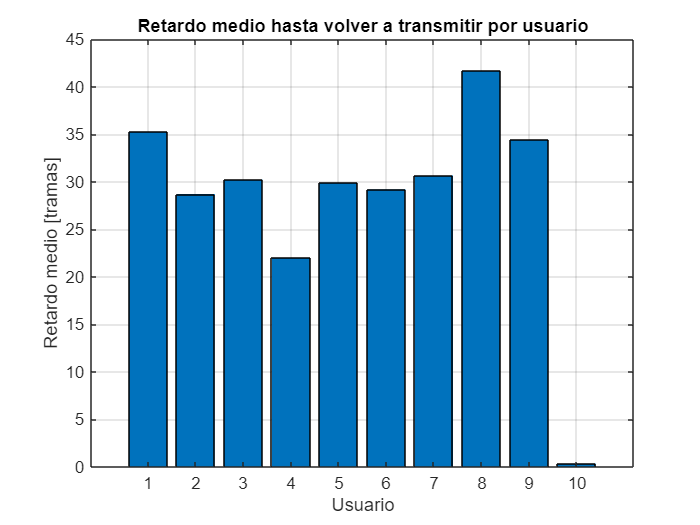


% Llamada al scheduler
[selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_muestras);
% Dibuja el retardo medio por usuario
plotMeanDelay(retardos);

% Mostrar el resultado final
disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

Usuario seleccionado final: 10      Vector de retardo final: 10   3  19   1  22  28  15  44  52   0


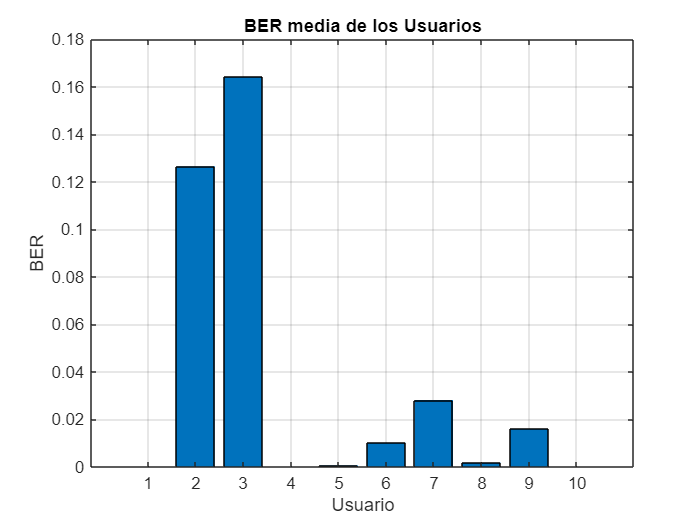


M = 16;
BER_avg = Calculate_BER(SNR_instantanea, M);

% Visualización de la BER media de los usuarios
figure;
bar(BER_avg); % Representación gráfica en barras
title('BER media de los Usuarios');
xlabel('Usuarios');
ylabel('BER');
grid on;

% Generación de bits a transmitir
num_bits = 4 * num_muestras; % 4 bits por símbolo
btx = randi([0 1], K, num_bits);

% Transmisión 16QAM
[brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);

% --- PDF del número total de tramas de espera ---
% Convertimos la variable 'retardos' en un solo vector
all_delays = cell2mat(retardos);

% Calculamos el total de tramas de espera sumando todos los retardos
total_tramas_espera = sum(all_delays);

% Representamos la PDF del número de tramas de espera
figure;
histogram(all_delays, 'Normalization', 'pdf');
xlabel('Número de tramas de espera');
ylabel('PDF');
title('PDF del número de tramas de espera por usuario');
grid on;
% --- Total de tramas de espera por usuario ---
% Sumamos los retardos para cada usuario (por fila de la celda 'retardos')
total_delays_per_user = cellfun(@sum, retardos);

% Representamos el total de retardos por usuario en un gráfico de barras
figure;
bar(1:K, total_delays_per_user);
xlabel('Usuario');
ylabel('Total de tramas de espera');
title('Total de tramas de espera por usuario');
grid on;






